clc,clear,close all
[I, map] = imread('CFig9.tif');
newmapR0 = map

newmapR0 =          0         0         0
    0.0627    0.0627    0.0314
    0.2902    0.0314         0
         0         0    1.0000
    0.2902    0.0627    0.0627
    0.3882    0.0314    0.0941
    0.4510    0.0627         0
    0.2588    0.1608    0.0627
    0.0941    0.2588    0.0314
    0.2235    0.1922    0.2235


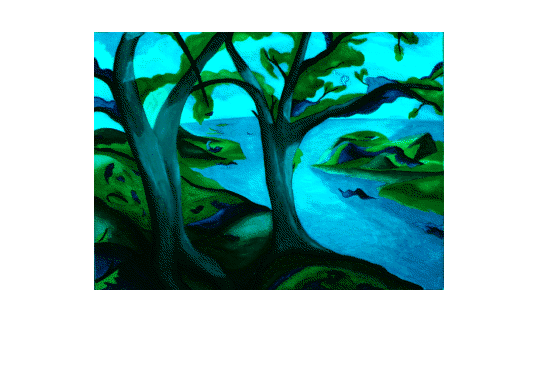

newmapR0(:,1) = 0;
imshow(I, newmapR0)

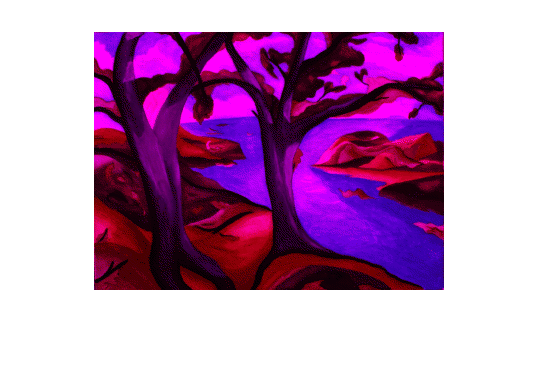

newmapG0 = map;
newmapG0(:,2) = 0;
imshow(I, newmapG0)

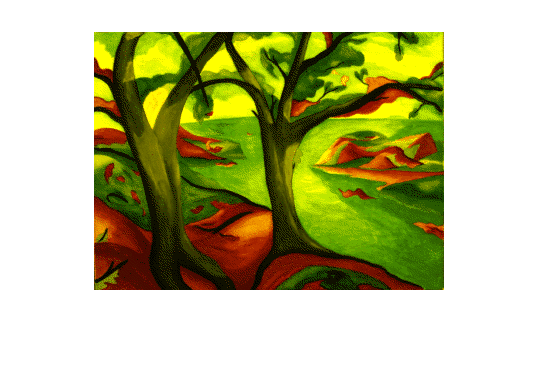

newmapB0 = map;
newmapB0(:,3) = 0;
imshow(I, newmapB0)

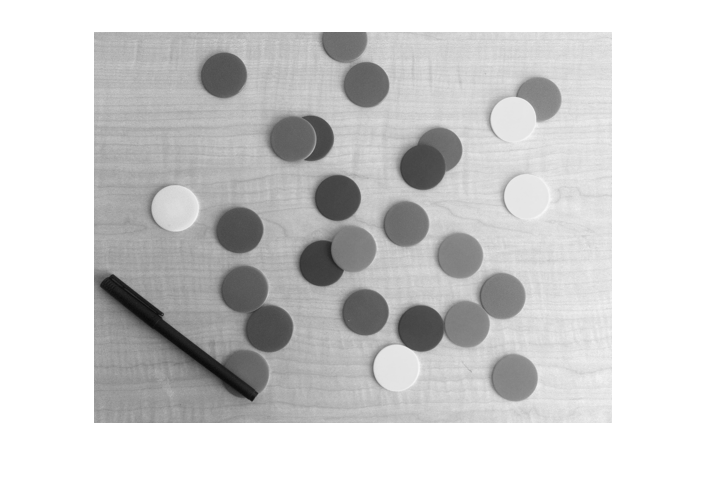

clc,clear
I = imread('CFig3.png');
J = rgb2gray(I);
imshow(J)

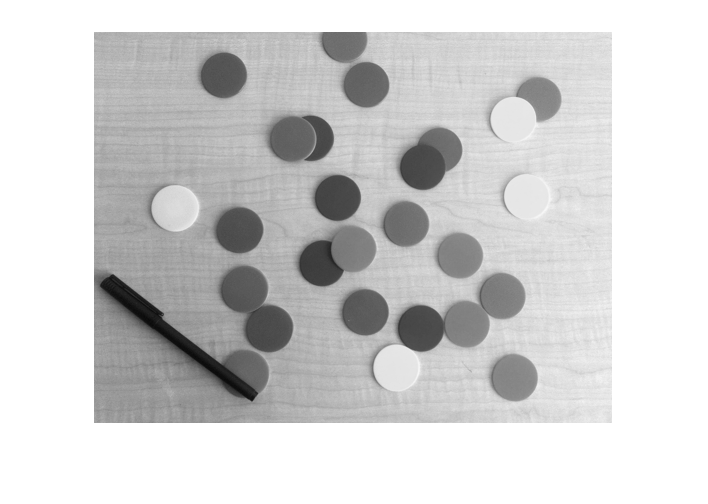

close all
[m,n,t]=size(I);
for i = 1:m
    for j = 1:n
        for k = 1:t
            J(i,j,k) = 0.299*I(i,j,1)+0.587*I(i,j,2)+0.11400*I(i,j,3);
        end
    end
end
imshow(J)

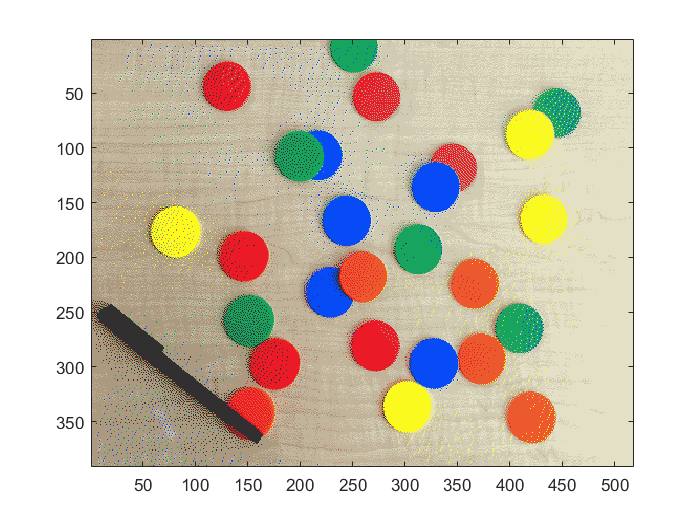

clc,clear
I = imread('CFig3.png');
[IND,map]  = rgb2ind(I,10);
figure
imagesc(IND)
colormap(map)

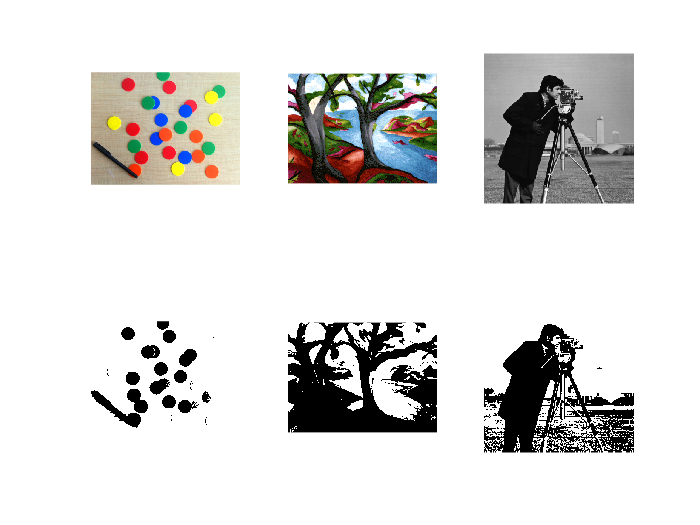

close all
I1 = imread('CFig3.png'); % RGB image
[I2, map] = imread('CFig9.tif'); % index image
I3 = imread('Fig0.tif'); % gray image
level = 0.5;
BW1 = im2bw(I1, level);
BW2 = im2bw(I2, map, level);
BW3 = im2bw(I3, level);
subplot(2,3,1), imshow(I1);
subplot(2,3,2), imshow(I2, map);
subplot(2,3,3), imshow(I3);
subplot(2,3,4), imshow(BW1);
subplot(2,3,5), imshow(BW2);
subplot(2,3,6), imshow(BW3);

close all
[X, map] = imread('CFig9.tif'); % index image
RGB = ind2rgb(X,map);
disp(['Range of RGB image is [',num2str(min(RGB(:))),', ',num2str(max(RGB(:))),'].'])

Range of RGB image is [0, 1].


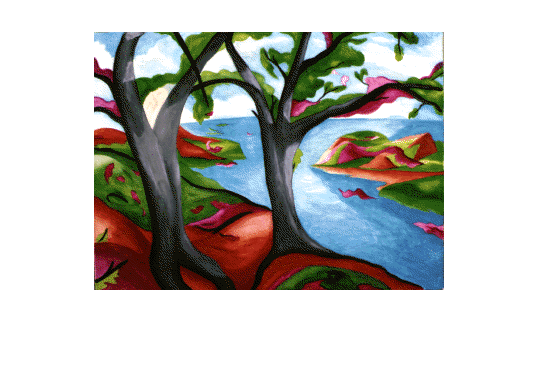

imshow(RGB)

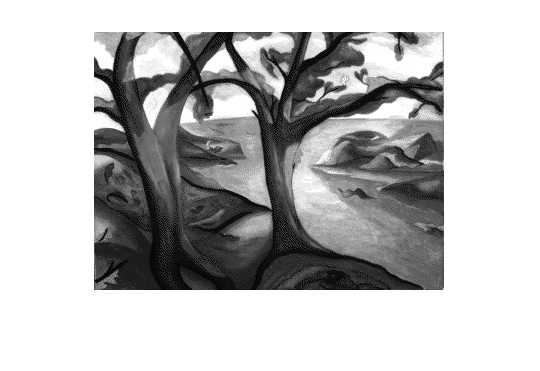

close all
[X, map] = imread('CFig9.tif'); % index image
gray = ind2gray(X,map);
imshow(gray)

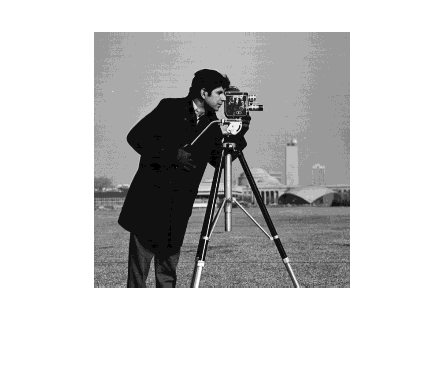

close all
I = imread('Fig0.tif'); % gray image
[X, map] = gray2ind(I, 16);
imshow(X, map);

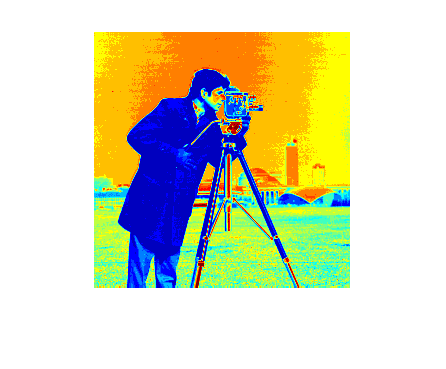

close all
I = imread('Fig0.tif'); % gray image
X = grayslice(I,16);
imshow(X,jet(16))

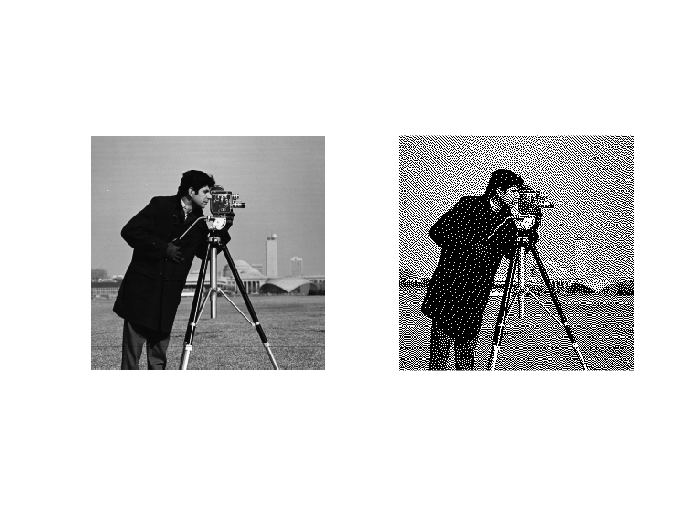

close all
%% 图像抖动
I = imread('Fig0.tif'); % gray image
subplot(1,2,1),imshow(I);
J = dither(I);
subplot(1,2,2),imshow(J);

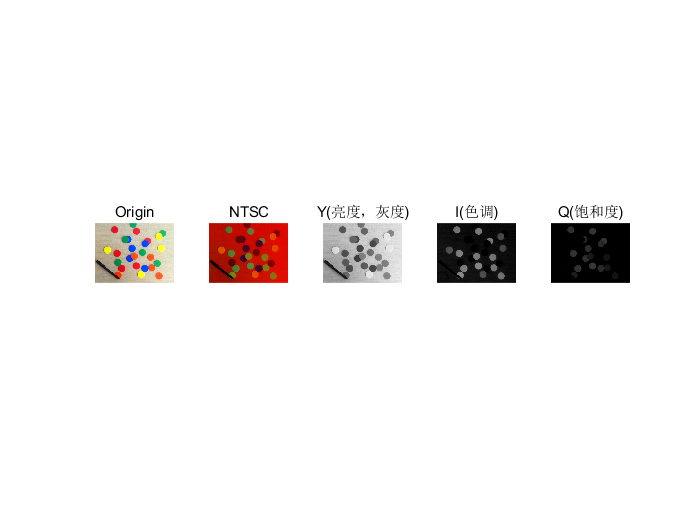

clc, clear, close all
origin = imread('CFig3.png');
% 1.NTSC彩色空间，由YIQ分量构成
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
% use rgb2ntsc to convert RGB to YIQ
yiqbyfun = rgb2ntsc(origin);
subplot(1,5,2), imshow(yiqbyfun(:,:,:)),title('NTSC')
subplot(1,5,3), imshow(yiqbyfun(:,:,1)),title('Y(亮度，灰度)')
subplot(1,5,4), imshow(yiqbyfun(:,:,2)),title('I(色调)')
subplot(1,5,5), imshow(yiqbyfun(:,:,3)),title('Q(饱和度)')

% use specific method to convert RGB to YIQ
R = origin(:,:,1);
G = origin(:,:,2);
B = origin(:,:,3);
A = im2double(origin); % RGB image must be double type first and [0,1] scale
[so(1),so(2),thirdD] = size(A); % get size
T = [1.0 0.956 0.621; 1.0 -0.272 -0.647; 1.0 -1.106 1.703].';
figure
yiqbyself = reshape(reshape(A,so(1)*so(2),thirdD)/T,so(1),so(2),thirdD);
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
subplot(1,5,2), imshow(yiqbyself(:,:,:)),title('NTSC')
subplot(1,5,3), imshow(yiqbyself(:,:,1)),title('Y(亮度，灰度)')
subplot(1,5,4), imshow(yiqbyself(:,:,2)),title('I(色调)')
subplot(1,5,5), imshow(yiqbyself(:,:,3)),title('Q(饱和度)')

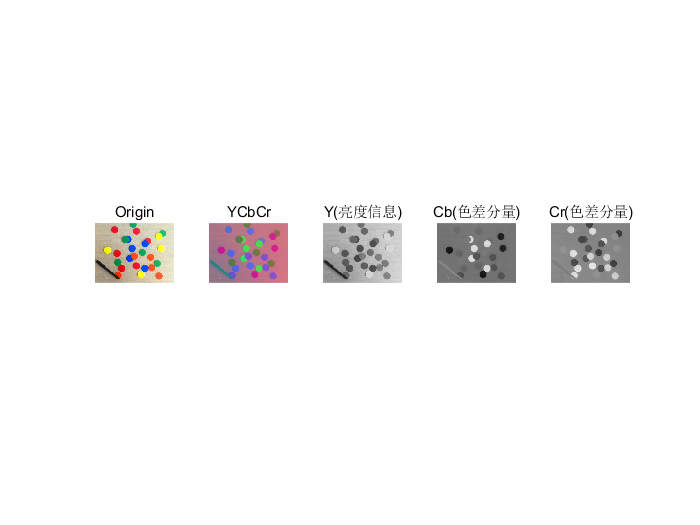

clc, clear, close all
origin = imread('CFig3.png');
% 2.YCrCb彩色空间，由Y,Cb,Cr分量构成
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
% use rgb2ntsc to convert RGB to YCbCr
ycbcrbyfun = rgb2ycbcr(origin);
subplot(1,5,2), imshow(ycbcrbyfun(:,:,:)),title('YCbCr')
subplot(1,5,3), imshow(ycbcrbyfun(:,:,1)),title('Y(亮度信息)')
subplot(1,5,4), imshow(ycbcrbyfun(:,:,2)),title('Cb(色差分量)')
subplot(1,5,5), imshow(ycbcrbyfun(:,:,3)),title('Cr(色差分量)')

% use specific method to convert RGB to YCbCr
R = origin(:,:,1);
G = origin(:,:,2);
B = origin(:,:,3);
A = im2double(origin); % RGB image must be double type first
[so(1),so(2),thirdD] = size(A); % get size
ycbcrbyself = zeros(so(1),so(2),thirdD);
ycbcrbyself(:,:,1) = 16 + 65.481*R + 128.553*G + 24.966*B; % Y
ycbcrbyself(:,:,2) = 128 - 37.797*R - 74.203*G + 112.000*B; % Cb
ycbcrbyself(:,:,3) = 128 + 112.000*R - 93.786*G - 18.214*B; % Cr
ycbcrbyself(:,:,1)  = (0.257 * R) + (0.504 * G) + (0.098 * B) + 16

ycbcrbyself = ycbcrbyself(:,:,1) =

   174   172   170   173   172   170   166   174   174   171   170   165   170   168   172   168   167   171   167   167   167   168   161   166   165   164   164   163   165   168   169   168   170   173   169   172   174   172   172   173   173   173   171   173   175   174   174   171   174   176   171   171   172   173   167   174   177   177   175   172   172   172   171   169   170   172   174   174   173   172   173   171   175   174   170   172   169   171   172   171   172   172   172   170   171   170   176   172   170   172   174   171   172   171   168   166   168   168   172   177   176   170   172   168   166   166   166   167   167   167   165   168   167   165   161   166   166   165   167   167   169   169   171   169   169   168   170   170   171   169   168   170   167   168   165   165   164   164   168   170   167   168   174   170   168   168   171   170   172   173   170   174   174   178   174   169   173   178   176   174   1

ycbcrbyself(:,:,2) = (0.439 * R) - (0.368 * G) - (0.071 * B) + 128

ycbcrbyself = ycbcrbyself(:,:,1) =

   174   172   170   173   172   170   166   174   174   171   170   165   170   168   172   168   167   171   167   167   167   168   161   166   165   164   164   163   165   168   169   168   170   173   169   172   174   172   172   173   173   173   171   173   175   174   174   171   174   176   171   171   172   173   167   174   177   177   175   172   172   172   171   169   170   172   174   174   173   172   173   171   175   174   170   172   169   171   172   171   172   172   172   170   171   170   176   172   170   172   174   171   172   171   168   166   168   168   172   177   176   170   172   168   166   166   166   167   167   167   165   168   167   165   161   166   166   165   167   167   169   169   171   169   169   168   170   170   171   169   168   170   167   168   165   165   164   164   168   170   167   168   174   170   168   168   171   170   172   173   170   174   174   178   174   169   173   178   176   174   1

ycbcrbyself(:,:,1) = -(0.148 * R) - (0.291 * G) + (0.439 * B) + 128

ycbcrbyself = ycbcrbyself(:,:,1) =

   174   172   170   173   172   170   166   174   174   171   170   165   170   168   172   168   167   171   167   167   167   168   161   166   165   164   164   163   165   168   169   168   170   173   169   172   174   172   172   173   173   173   171   173   175   174   174   171   174   176   171   171   172   173   167   174   177   177   175   172   172   172   171   169   170   172   174   174   173   172   173   171   175   174   170   172   169   171   172   171   172   172   172   170   171   170   176   172   170   172   174   171   172   171   168   166   168   168   172   177   176   170   172   168   166   166   166   167   167   167   165   168   167   165   161   166   166   165   167   167   169   169   171   169   169   168   170   170   171   169   168   170   167   168   165   165   164   164   168   170   167   168   174   170   168   168   171   170   172   173   170   174   174   178   174   169   173   178   176   174   1

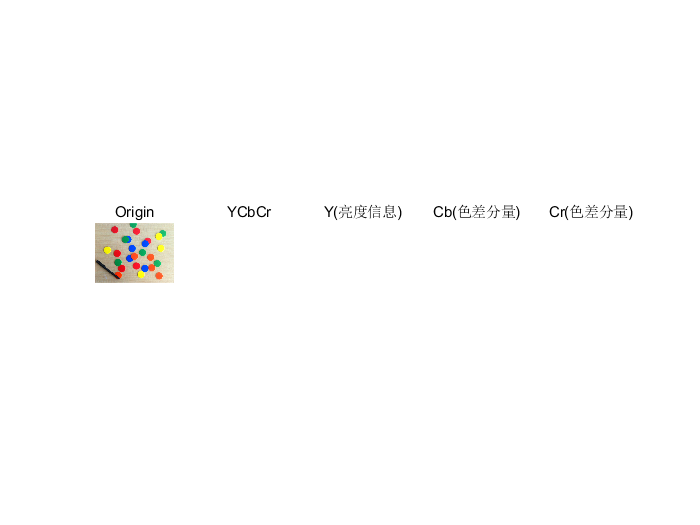

figure
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
subplot(1,5,2), imshow(ycbcrbyself(:,:,:)),title('YCbCr')
subplot(1,5,3), imshow(ycbcrbyself(:,:,1)),title('Y(亮度信息)')
subplot(1,5,4), imshow(ycbcrbyself(:,:,2)),title('Cb(色差分量)')
subplot(1,5,5), imshow(ycbcrbyself(:,:,3)),title('Cr(色差分量)')

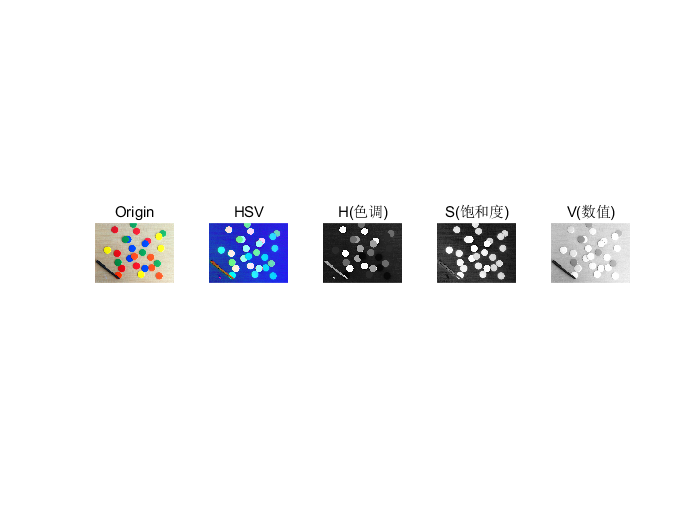

clc, clear, close all
origin = imread('CFig3.png');
% 3.HSV彩色空间，由H,S,V分量构成
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
% use rgb2hsv to convert RGB to HSV
hsvbyfun = rgb2hsv(origin);
subplot(1,5,2), imshow(hsvbyfun(:,:,:)),title('HSV')
subplot(1,5,3), imshow(hsvbyfun(:,:,1)),title('H(色调)')
subplot(1,5,4), imshow(hsvbyfun(:,:,2)),title('S(饱和度)')
subplot(1,5,5), imshow(hsvbyfun(:,:,3)),title('V(数值)')

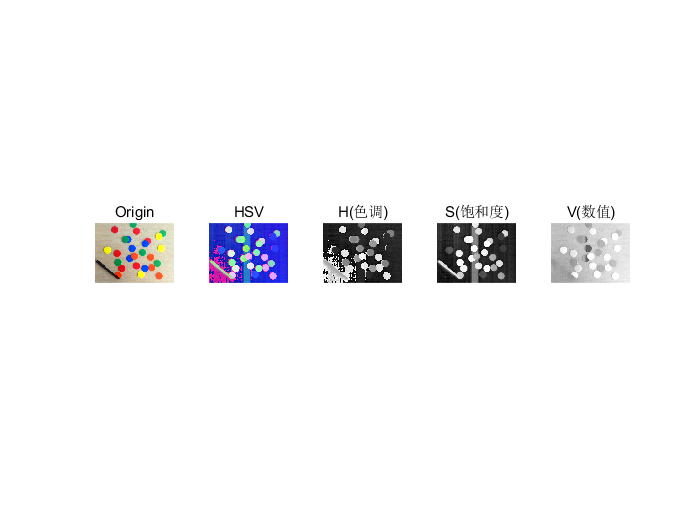

% use specific method to convert RGB to HSV
hsvbyself = rgb2hsv_r(origin);
figure
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
subplot(1,5,2), imshow(hsvbyself(:,:,:)),title('HSV')
subplot(1,5,3), imshow(hsvbyself(:,:,1)),title('H(色调)')
subplot(1,5,4), imshow(hsvbyself(:,:,2)),title('S(饱和度)')
subplot(1,5,5), imshow(hsvbyself(:,:,3)),title('V(数值)')

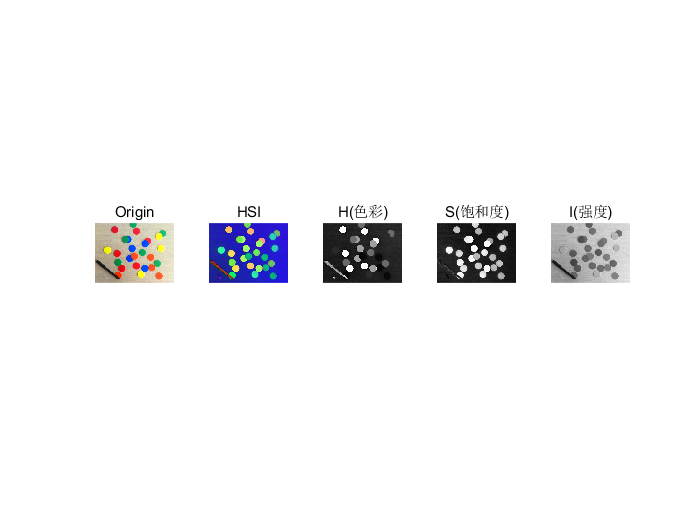

clc, clear, close all
origin = imread('CFig3.png');
% 4.HSI彩色空间，由H,S,I分量构成
subplot(1,5,1), imshow(origin),title('Origin') % this is a RGB image
% use rgb2hsi to convert RGB to HSI
hsibyfun = rgb2hsi(origin);
subplot(1,5,2), imshow(hsibyfun(:,:,:)),title('HSI')
subplot(1,5,3), imshow(hsibyfun(:,:,1)),title('H(色彩)')
subplot(1,5,4), imshow(hsibyfun(:,:,2)),title('S(饱和度)')
subplot(1,5,5), imshow(hsibyfun(:,:,3)),title('I(强度)')

A = im2double(origin); % RGB image must be double type first and [0,1] scale
[so(1),so(2),thirdD] = size(A); % get size
hsibyself = ones(so(1),so(2),thirdD);
for j = 1:so(1)
    for k = 1:so(2)
        [H,S,I] = rgb2hisPixel(A(j,k,1),A(j,k,2),A(j,k,3));
        hsibyself(j,k,1) = H;
        hsibyself(j,k,2) = S;
        hsibyself(j,k,3) = I;
    end
end
subplot(1,5,2), imshow(hsibyself(:,:,:)),title('HSI')

subplot(1,5,3), imshow(hsibyself(:,:,1)),title('H(色彩)')

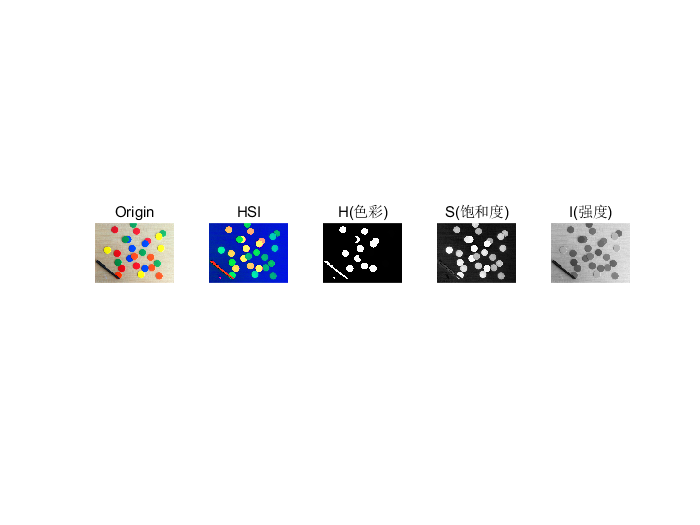

subplot(1,5,4), imshow(hsibyself(:,:,2)),title('S(饱和度)')
subplot(1,5,5), imshow(hsibyself(:,:,3)),title('I(强度)')

function hsi = rgb2hsi(rgb)
rgb = im2double(rgb);
r = rgb(:, :, 1);
g = rgb(:, :, 2);
b = rgb(:, :, 3);
% Implement the conversion equations.
num = 0.5*((r - g) + (r - b));
den = sqrt((r - g).^2 + (r - b).*(g - b));
theta = acos(num./(den + eps));
H = theta;
H(b > g) = 2*pi - H(b > g);
H = H/(2*pi);
num = min(min(r, g), b);
den = r + g + b;
den(den == 0) = eps;
S = 1 - 3.* num./den;
H(S == 0) = 0;
I = (r + g + b)/3;
% Combine all three results into an hsi image.
hsi = cat(3, H, S, I);
end

function [H,S,I] = rgb2hisPixel(R,G,B)
    theta = acos((0.5*(R-G+R-B))/(sqrt((R-G)^2+(R-B)*(G-B))));
    if B <= G
        H = theta/360;
    else
        H = (360 - theta)/360;
    end
    S = 1 - (3/(R+G+B))*(min(min(R,G),B));
    I = (R+G+B)/3;
end

function hsv=rgb2hsv_r(rgb)
r1=rgb(:,:,1);
g1=rgb(:,:,2);
b1=rgb(:,:,3);
if isa(r1, 'uint8')
    r1 = double(r1) / 255;
elseif isa(r1, 'uint16')
    r1 = double(r1) / 65535;
end

if isa(g1, 'uint8')
    g1= double(g1) / 255;
elseif isa(g1, 'uint16')
    g1 = double(g1) / 65535;
end

if isa(b1, 'uint8')
    b1 = double(b1) / 255;
elseif isa(b1, 'uint16')
    b1 = double(b1) / 65535;
end
dim = size(r1);
h1=zeros(size(r1));
s1=zeros(size(r1));
v1=zeros(size(r1));

for i=1:dim(1,1)
    for j=1:dim(1,2)
        r=r1(i,j);
        g=g1(i,j);
        b=b1(1,j);
        Max= max(max(g,b),r);
        Min=min(min(b,g),r);
        
        delta=Max-Min;
        v=Max;
        if(Max~=0.0)
            s=delta/Max;
        else
            s=0.0;
        end
        if s==0.0
            
            h=0;
        else
            if r==Max
                h=(g-b)/delta;
            elseif g==Max
                h=2.0+(b-r)/delta;
            elseif b==Max
                h=4.0+(r-g)/delta;
            end
            h=h*60.0;
            if(h<0)
                h=h+360.0;
            end
            h=h/360.0;
            
        end
        h1(i,j)=h;
        s1(i,j)=s;
        v1(i,j)=v;
    end
end
hsv(:,:,1)=h1;
hsv(:,:,2)=s1;
hsv(:,:,3)=v1;
end